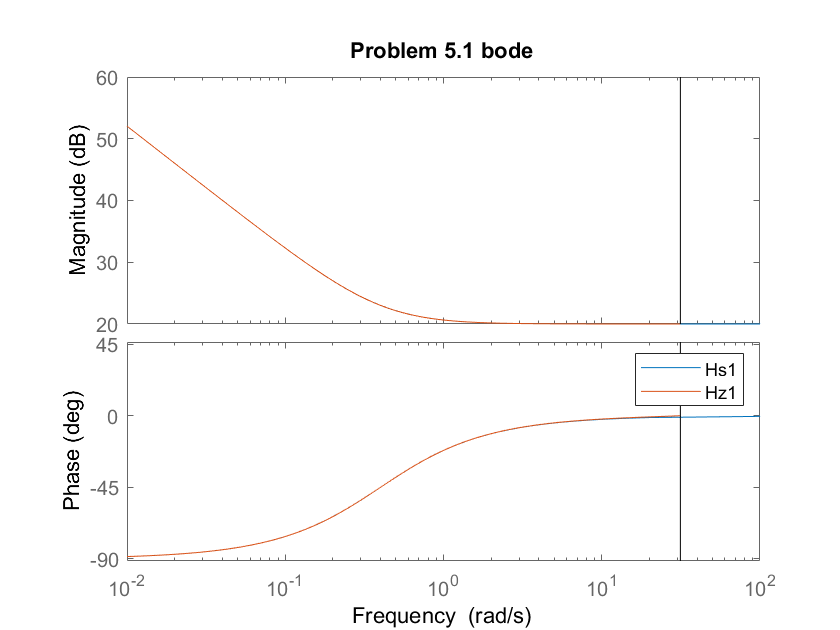

%% Problem 6.1 %%
close all;
s = tf('s');
P1 = 10;                                                %5.1
I1 = 4;                                                 %5.1
Beta_2 = 3;                                             %5.2
w1_2 = .111/sqrt(Beta_2);                               %5.2
w_c_3 = 100;                                            %5.3                    
phi_max_3a = 55;                                        %5.3
beta_3a = (1+sind(phi_max_3a))/(1-sind(phi_max_3a));    %5.3
w_3a = w_c_3/sqrt(beta_3a);                             %5.3
alpha_4 = 6.32;                                         %5.4
wc_4 = 7;                                               %5.4
w1_4 = wc_4/(10*alpha_4);                               %5.4
lambda_4c = 0.1;                                        %5.4c
beta_4c = 3*lambda_4c;                                  %5.4c
beta_5 = (1+sind(16))/(1-sind(16));                     %5.5
w1a_5=sqrt(1000/sqrt(beta_5));                          %5.5
lambda_5e = .05;                                        %5.5e
beta_5e = 3*lambda_5e;                                  %5.5e
Gs_5 = tf([5],[0.05 1 0]);                              %5.5e
fs_5e = (1+beta_5e*s)/(1+lambda_5e*s)^3;                %5.5e
Ts_5e = fs_5e;                                          %5.5e
Qs_5e = Ts_5e/Gs_5;                                     %5.5e
Gs_6 = tf([-1.117 3.1472], [1 4.6429 5.3821]);          %5.6
lambda_6 = .1;                                          %5.6
beta_6 = .3;                                            %5.6
Gsa_6 = tf([-1.117 3.1472],[1.117 3.1472]);             %5.6
fs_6 = (1+beta_6*s)/(1+lambda_6*s)^3;                   %5.6
Ts_6 = fs_6*Gsa_6;                                      %5.6
Qs_6 = Ts_6/Gs_6;                                       %5.6
Gs_7 = 1/s;                                             %5.7
lambda_7 = .5;                                          %5.7
beta_7 = 4*.3;                                          %5.7
fs_7 = (1+beta_7*s)/(1+lambda_7*s)^4;                   %5.7
Ts_7 = fs_7;                                            %5.7
Qs_7 = Ts_7/Gs_7;                                       %5.7

Hs1 = tf(P1 + I1/s);
csys1 = SOFdis(Hs1);
h1 = 0.1;
Hz1 = myDiscretize(Hs1, h1, 'tustin');
figure;
bode(Hs1);
hold on;
bode(Hz1);
legend;
title("Problem 5.1 bode");
hold off;

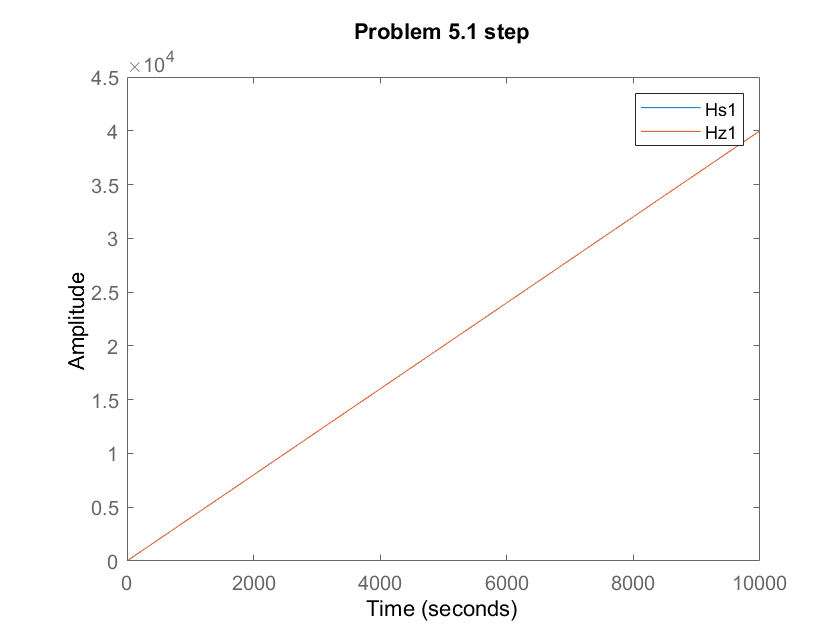

figure;
step(Hs1);
hold on;
step(Hz1);
legend;
title("Problem 5.1 step")
hold off;

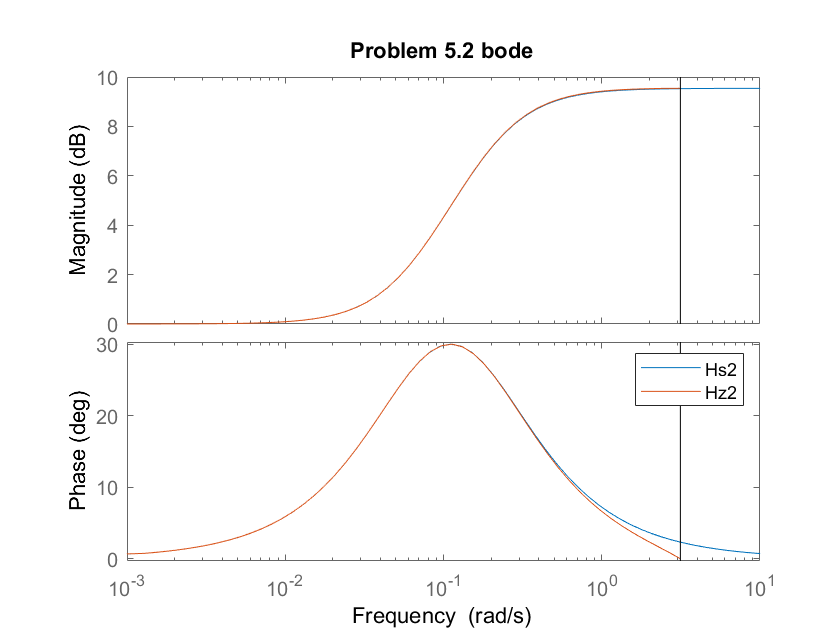


Hs2 = (1+s/w1_2)/(1+s/(Beta_2*w1_2));
h2 = 1;
Hz2 = myDiscretize(Hs2, h2, 'tustin');
figure;
bode(Hs2);
hold on;
bode(Hz2);
legend;
title("Problem 5.2 bode");
hold off;

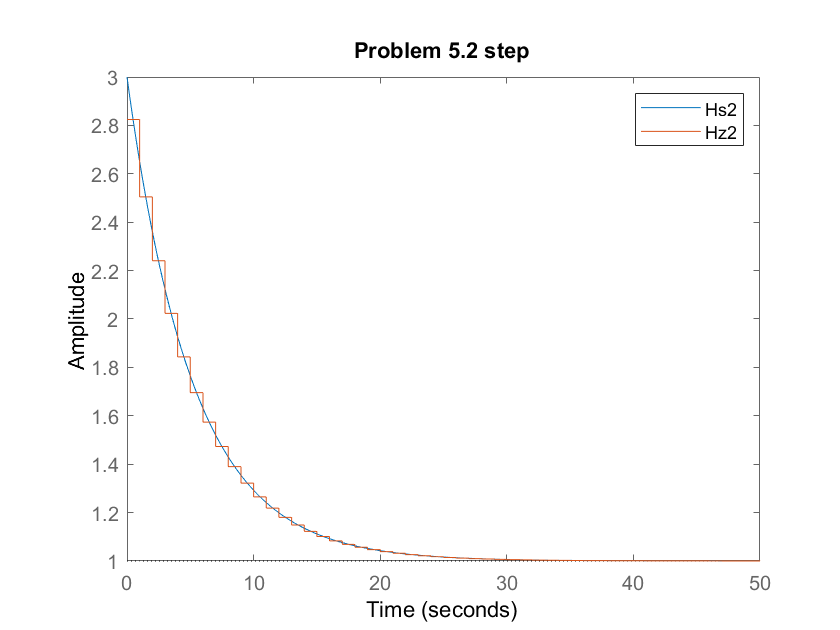

figure;
step(Hs2);
hold on;
step(Hz2);
legend;
title("Problem 5.2 step")
hold off;

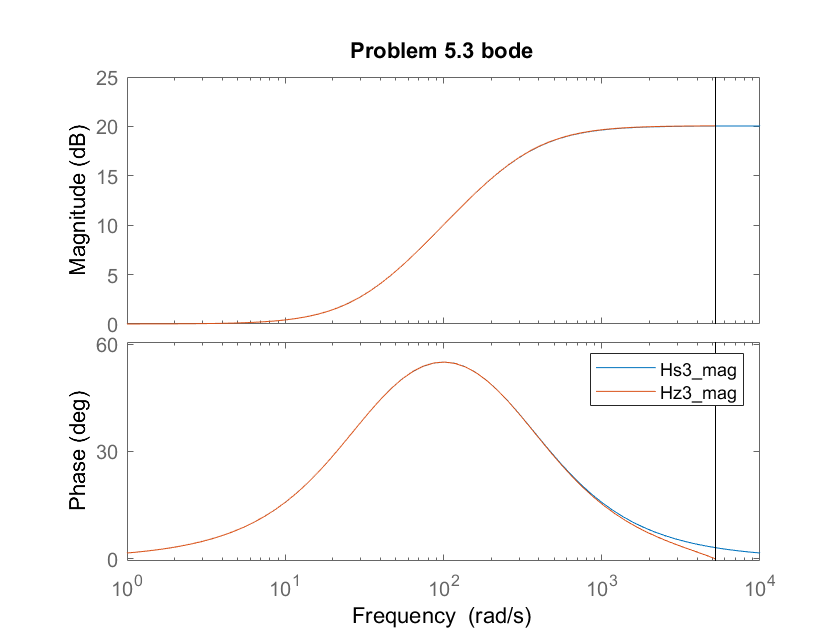


Hs3_mag = (1+s/w_3a)/(1+s/(w_3a*beta_3a));
h3 = .0006;
Hz3_mag = myDiscretize(Hs3_mag, h3, 'tustin');
% For inverted pendulum, used an SVFB controller so I did not discretize
% that using Tustin
figure;
bode(Hs3_mag);
hold on;
bode(Hz3_mag);
legend;
title("Problem 5.3 bode");
hold off;

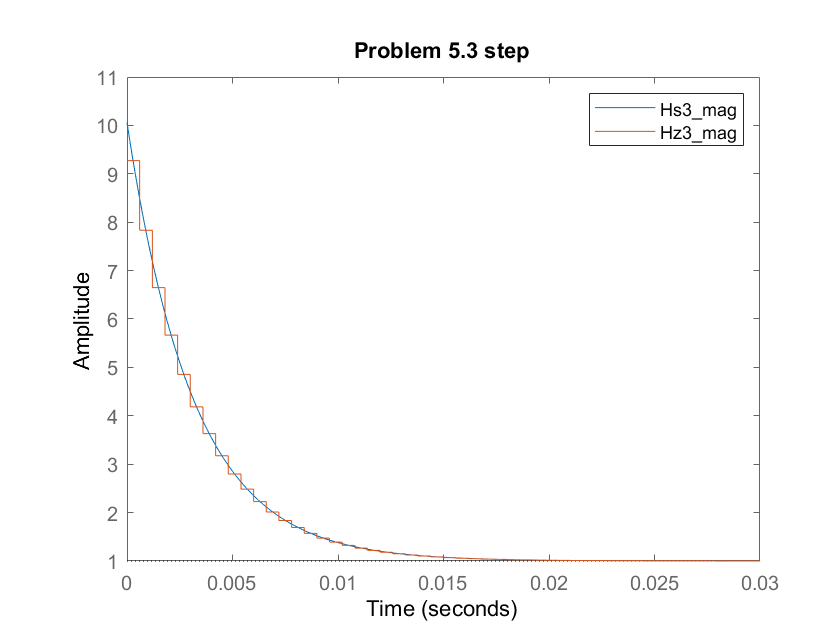

figure;
step(Hs3_mag);
hold on;
step(Hz3_mag);
legend;
title("Problem 5.3 step")
hold off;

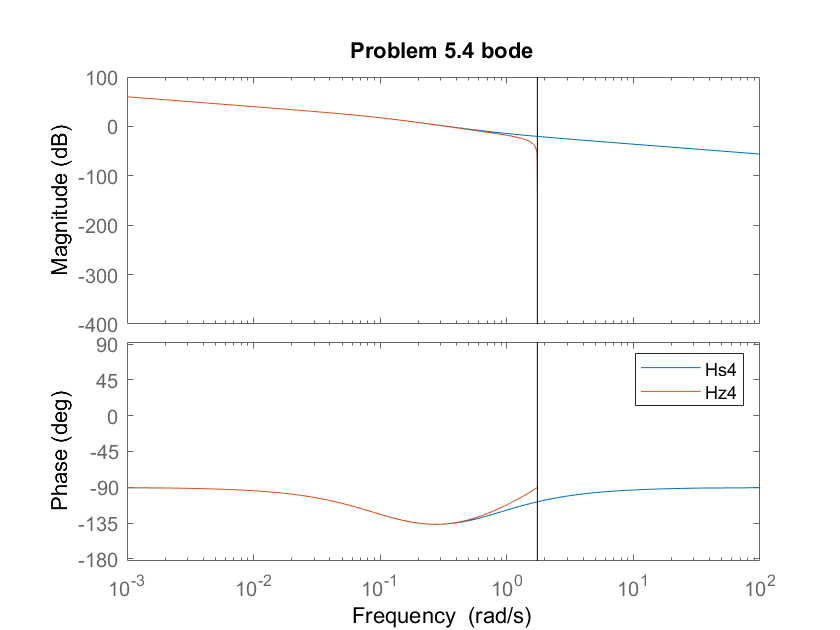


Hs4 = (1/s)*(1+s/(alpha_4*w1_4))/(1+s/w1_4);
h4 = 1.8;
Hz4 = myDiscretize(Hs4, h4, 'tustin');
Hs4c = (1+beta_4c*s)*(1+.08*s)^2/((1+lambda_4c*s)^3 - (1+beta_4c*s));
h4c = .006;
Hz4c = myDiscretize(Hs4c, h4c, 'tustin');
figure;
bode(Hs4);
hold on;
bode(Hz4);
legend;
title("Problem 5.4 bode");
hold off;

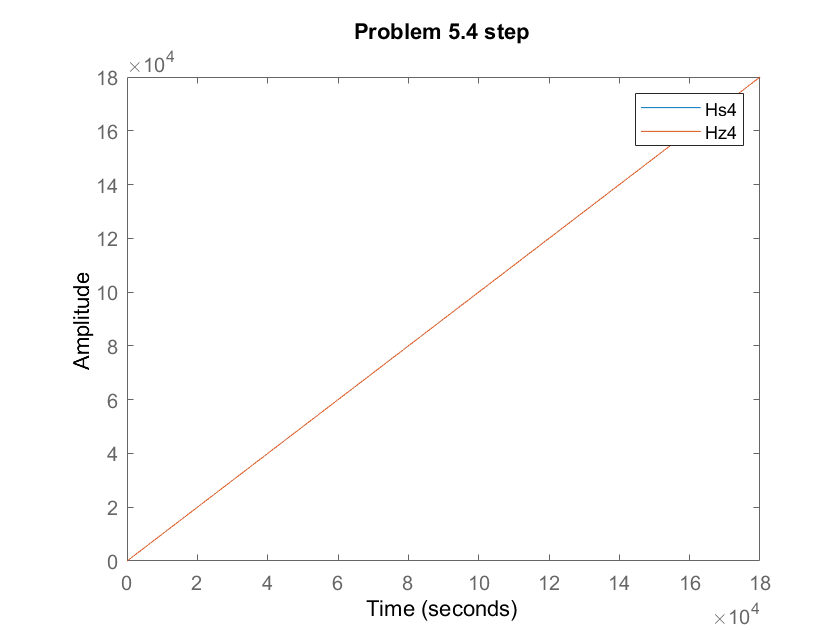

figure;
step(Hs4);
hold on;
step(Hz4);
legend;
title("Problem 5.4 step")
hold off;

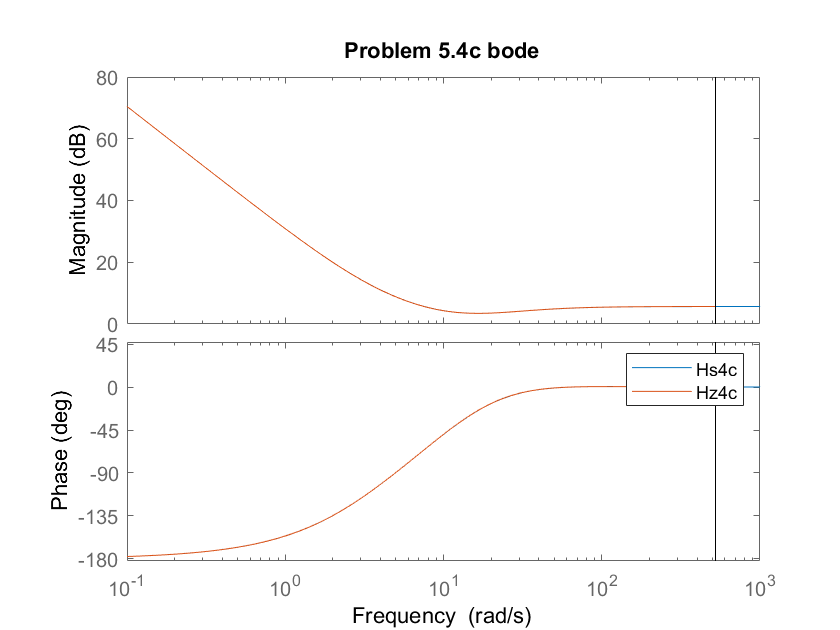

figure;
bode(Hs4c);
hold on;
bode(Hz4c);
legend;
title("Problem 5.4c bode");
hold off;

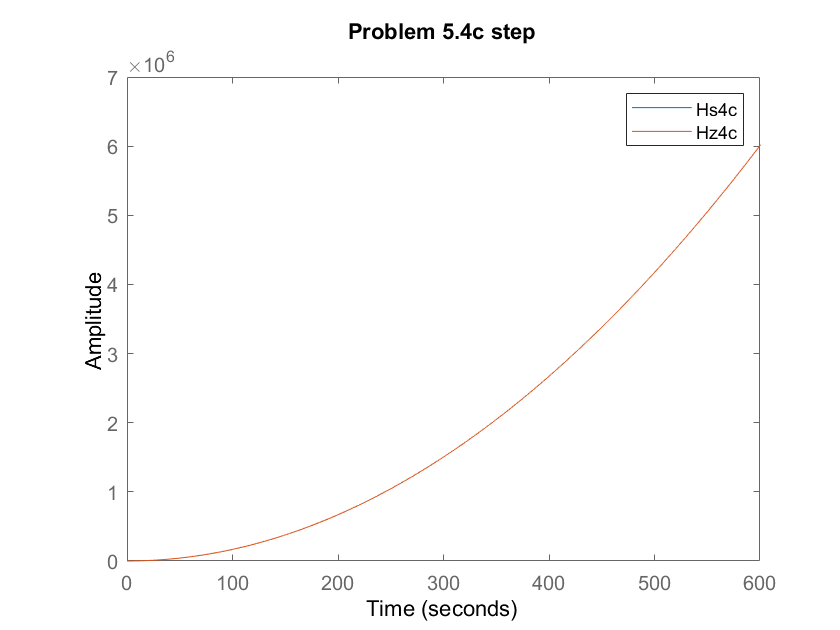

figure;
step(Hs4c);
hold on;
step(Hz4c);
legend;
title("Problem 5.4c step")
hold off;

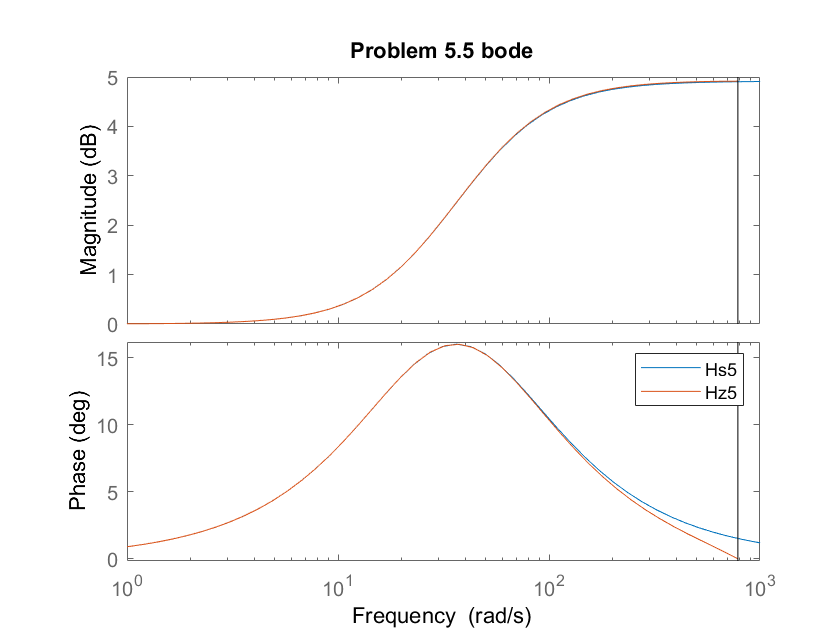


Hs5 = (1+s/w1a_5)/(1+s/(w1a_5*beta_5));
h5 = .004;
Hz5 = myDiscretize(Hs5, h5, 'tustin');
Hs5e = Qs_5e/(1-Ts_5e);
h5e = .003;
Hz5e = c2d(Hs5e, h5e, 'tustin');
figure;
bode(Hs5);
hold on;
bode(Hz5);
legend;
title("Problem 5.5 bode");
hold off;

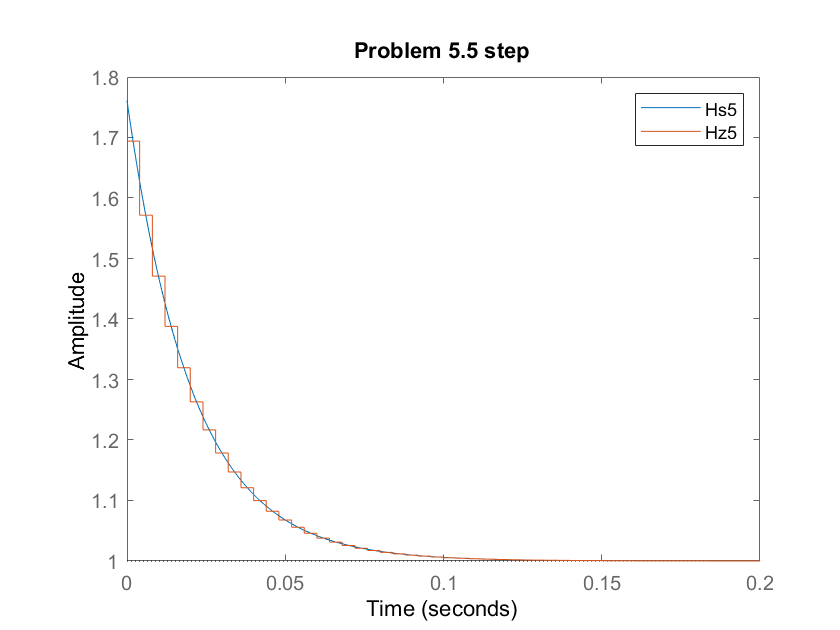

figure;
step(Hs5);
hold on;
step(Hz5);
legend;
title("Problem 5.5 step")
hold off;

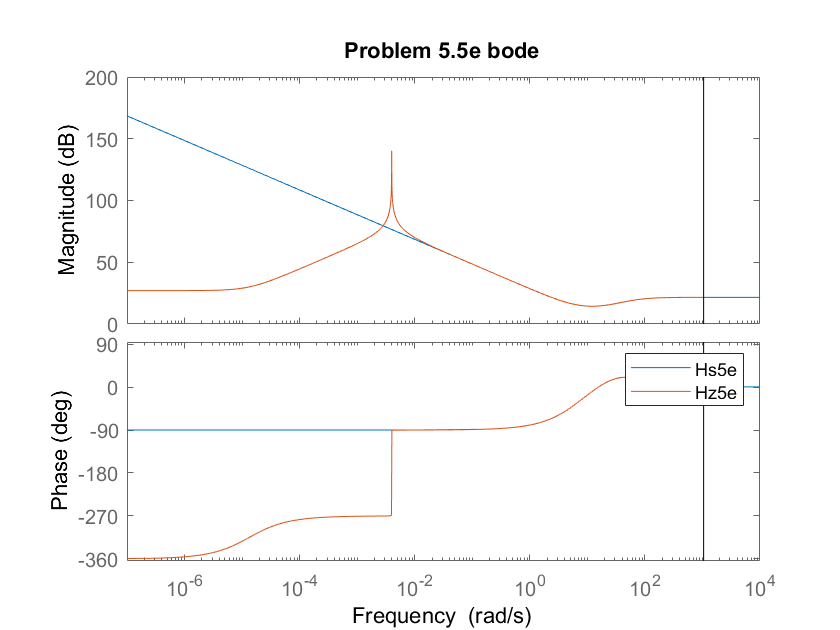

figure;
bode(Hs5e);
hold on;
bode(Hz5e);
legend;
title("Problem 5.5e bode");
hold off;

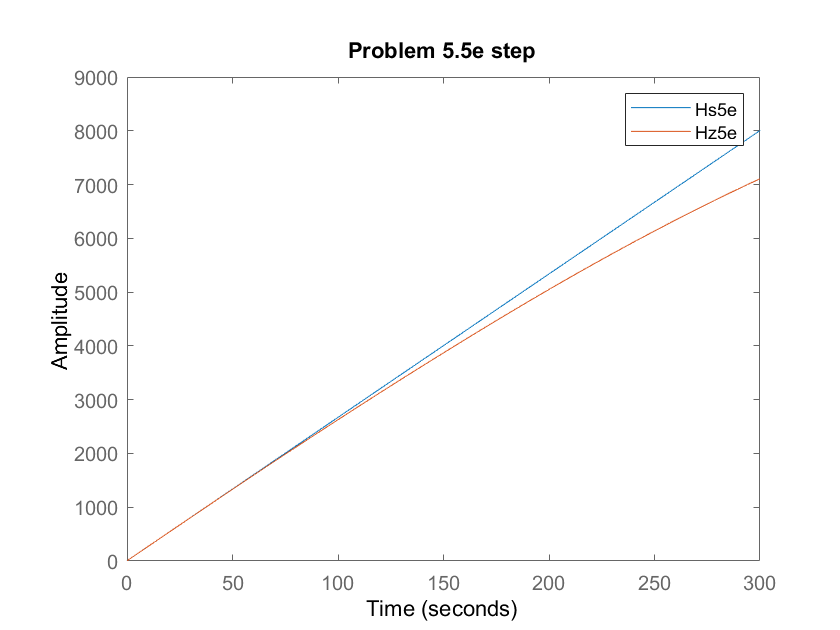

figure;
step(Hs5e);
hold on;
step(Hz5e);
legend;
title("Problem 5.5e step")
hold off;

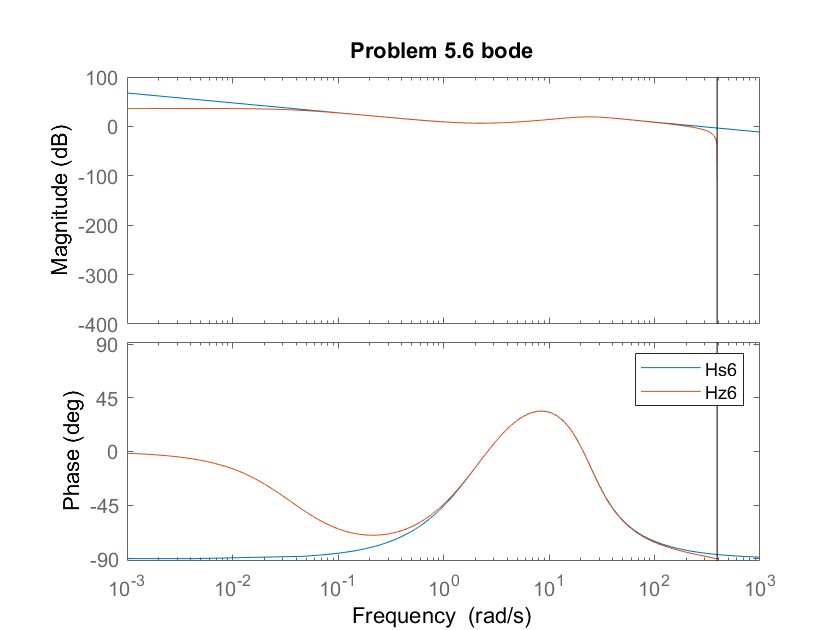


Hs6 = Qs_6/(1-Ts_6);
h6 = .008;
Hz6 = myDiscretize(Hs6, h6, 'tustin');
figure;
bode(Hs6);
hold on;
bode(Hz6);
legend;
title("Problem 5.6 bode");
hold off;

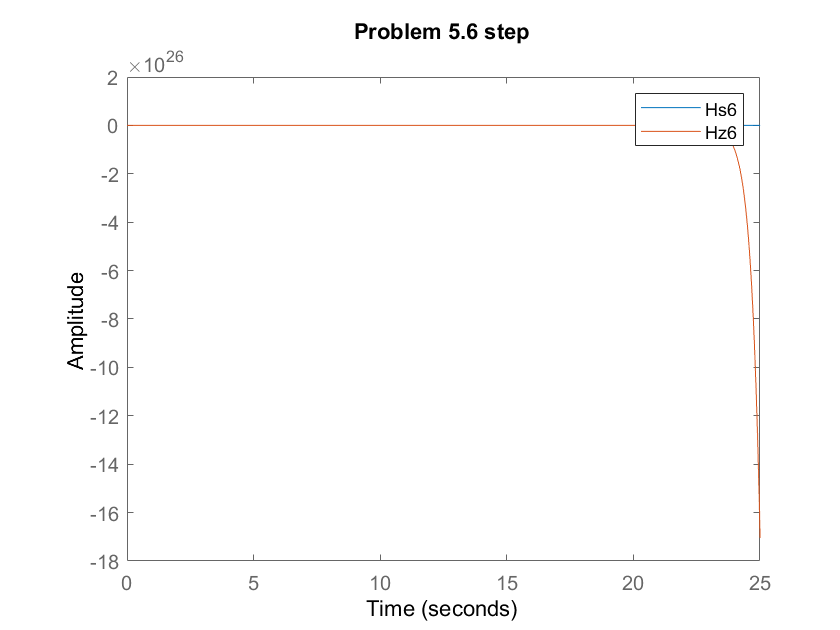

figure;
step(Hs6);
hold on;
step(Hz6);
legend;
title("Problem 5.6 step")
hold off;

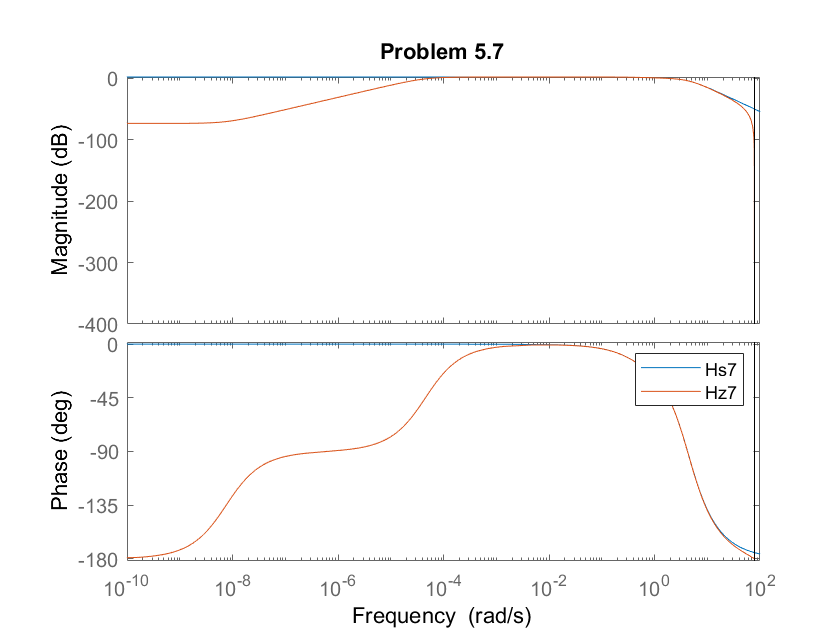


Hs7 = Qs_7/(1-Ts_7);
h7 = .04;
Hz7 = myDiscretize(Hs7, h7, 'tustin');
figure;
bode(Hs7);
hold on;
bode(Hz7);
legend;
title("Problem 5.7");
hold off;

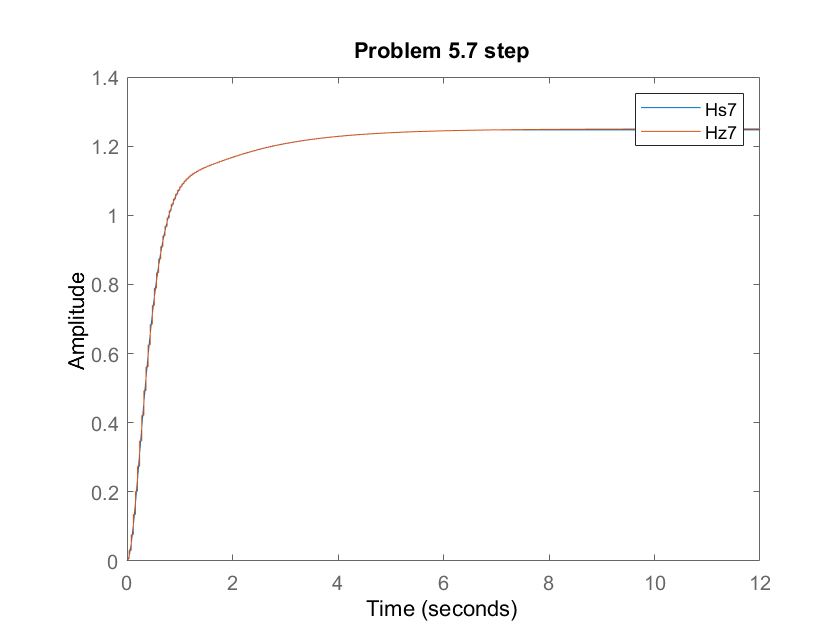

figure;
step(Hs7);
hold on;
step(Hz7);
legend;
title("Problem 5.7 step")
hold off;

Most controllers are accurate for mid-range frequencies.

Note that digitizing continuous IMC controllers can turn out disastrous (e.g. Problem 6).